# Solving the Schroindger Equation 

initial 

k0^2/v0

ans = 2

ej = zeros( 1, J );
fj = zeros( N , J   );
psi = zeros( N , J  );
x = linspace( -1/2 , 1/2 ,  J );
omega = zeros( N , J );

x1 = x <= hw ;
x2 = x >= -hw ;
x3 =  times( x1 , x2 );
vj =   v0 .* x3 ;
vj_plot =  ( 1/2 ) .* x3 ;

ej( 1 ) = 2 + e^2 * vj( 1 ) - 1i * l ;
ej = ej_rec( ej , vj , e , 2, J , l  ); 

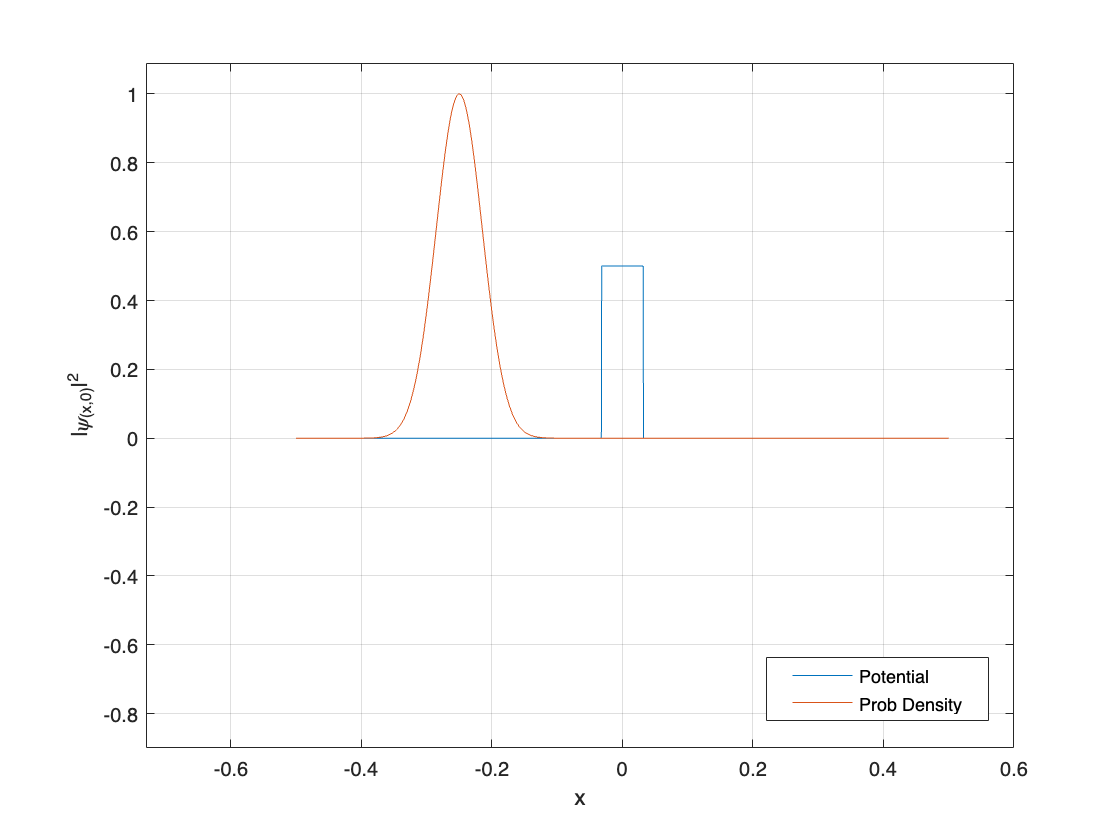

temp = my_psi_zero( x , k0 , sig0 );
psi( 1 , : ) = temp ;
temp2 = conj( temp ) .* temp ;
plot( x , vj_plot )
hold on 
plot( x , temp2 )
hold off 

xlim([-0.73 0.60])
ylim([-0.90 1.09])
xlabel("x")
ylabel("|\psi_{(x,0)}|^{2}")
grid on
legend(["Potential","Prob Density"])
legend("Position", [0.68431,0.14194,0.19914,0.075714])

o = zeros( 1 , J );
o( 1 ) = -psi( 1 , 2 ) + ( 1i * l + e^2 * vj( 1 ) + 2)*psi( 1 , 1 );
o = omega_rec( o , e , psi , vj , 1 );
omega( 1 , : ) = o ; 

f = zeros( 1, J ); 
f( 1 ) =  omega( 1 , 1 ); 
f = f_rec( f , 2 , omega( 1 , : ) , ej );
fj( 1 , : ) = f ;

[ psi , omega , fj ] = build_psi( psi , omega , fj , ej , vj , 2 , e , N , J ) ; 
psi = conj( psi ) .* psi ;

delta = 2 * e * e ; 
timestamp = 1:N ; 
timestamp = delta .* timestamp ; 

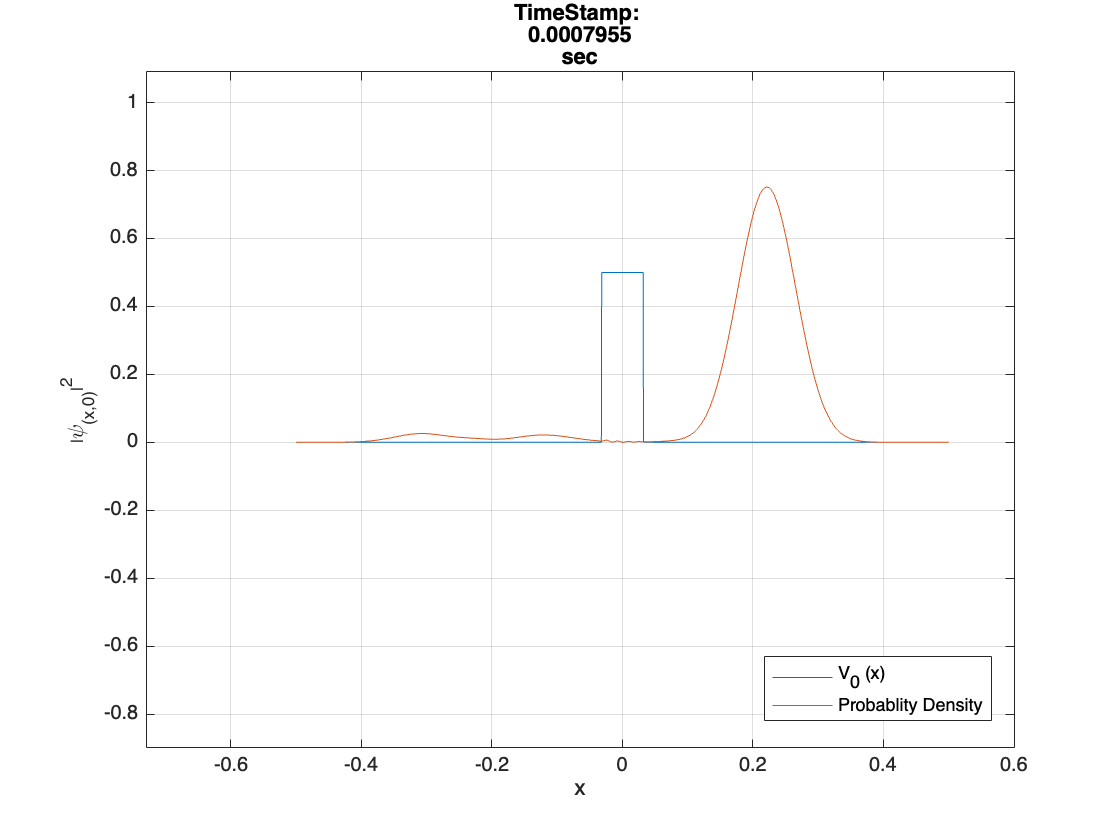

figh = figure ;


for i = 1:N

    clf 

    plot( x , vj_plot )
    hold on 
    plot( x , psi( i , : ) )
    hold off 
    
    xlim([-0.73 0.60])
    ylim([-0.90 1.09])
    xlabel("x")
    ylabel("|\psi_{(x,0)}|^{2}")
    grid on
    legend(["V_0 (x)","Probablity Density"])
    legend("Position", [0.68431,0.14194,0.19914,0.075714])
    title([ "TimeStamp: " , num2str( timestamp( i )) , "sec"] )

    movie( i  ) = getframe( figh , [ 20 10 520 410] ) ; 


end

wit = VideoWriter('2+' , 'MPEG-4'); 
wit.FrameRate = 30 ; 

open(wit);
writeVideo( wit , movie )
close( wit ); 

save( 'psi2_plus.mat' , 'movie' , '-v7.3')